(3.112)

Evaluate the frequency response of the truncated filter in Example 3.46. You can do this in MATLAB by writing an m-file to evaluate 


$$H_t (e^{j\Omega}) = \sum_{n=-M}^{M}{h[n]e^{-j\Omega n}} $$


for a large number (> 1000) of values of $\Omega$ in the interval $-\pi < \Omega \leq \pi$ Plot the frequency response magnitude in dB $(20log_{10}|H_t(e^{j\Omega})|)$ for the following values of M:

(a) M=4

(b) M=10

(c) M=25

(d) M=50

Discuss the effect of increasing M on the accuracy with which $H_t(e^{j\Omega})$ approximates $H(e^{j\Omega})$.

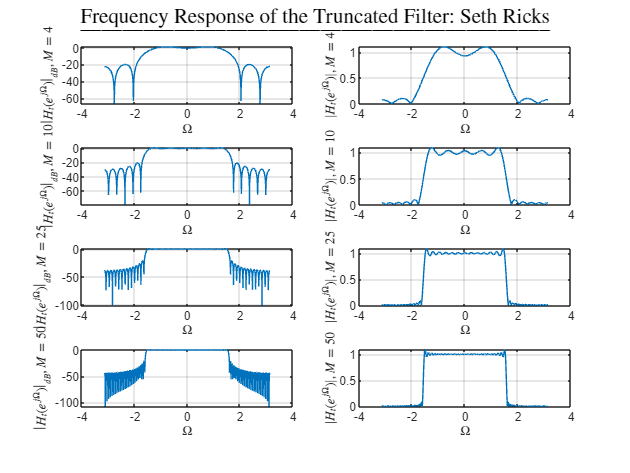

% From "W08_PS8 Examples_wide_25to54.pdf" in Canvas
% MATLAB script for MATLAB 3.112
clear
M = [4,10,25,50];  % M = 166 makes a cool logo in dB plot
for k = 1:4
    Ht = 0;
    Omega = -pi:pi/1000:pi;
    for n = -M(k):M(k)
        if n ~= 0
            hn = 1/pi/n*sin(pi*n/2);
        else
            hn = 1/2;
        end
        Ht = Ht + hn*exp(-1j*Omega*n);
    end
    Htmag = abs(Ht);
    HtdB = 20*log10(abs(Ht));
    figure(1)
    subplot(4,2,2*k-1)
    plot(Omega, HtdB)
    grid on
    xlabel('$\Omega$', 'interpreter', 'latex')
    y_str = sprintf('%s%i%s', '$\left| H_t(e^{j\Omega}) \right|_{dB}, M=', M(k), '$');
    ylabel(y_str, 'Interpreter', 'latex')

    subplot(4,2,2*k)
    plot(Omega, Htmag)
    grid on
    xlabel('$\Omega$', 'interpreter', 'latex')
    y_str = sprintf('%s%i%s', '$|H_t(e^{j\Omega})|, M=', M(k), '$');
    ylabel(y_str, 'Interpreter', 'latex')
end
sgtitle('\underline{Frequency Response of the Truncated Filter: Seth Ricks}', 'Interpreter', 'latex'); % Overall Title